# Impact of nutrient source on acetylation and methylation

## Load important variables

## Simulating nutrient supplementation and deprivation

This module visualizes the effect of nutrient perturbation on each histone reaction with respect to a control metabolic model as the threshold. I am showing the optimization schemes for methods of obtaining the histone activity coefficients `zeta`, which was selected by its ability to maximize the variance across histone reactions under different medium condtions and cancer-cell line specific cases while simultaneously optimizing the biomass objective function.

### Computing the baseline flux without medium perturbation in MEM

To establish a benchmark, the baseline histone reaction fluxes without medium perturbation were calculated. A `zeta` value of `1E-6` was used as an arbitrary coefficient to maximize each flux individually and in combination. Further, the default medium condition was minimal medium, which is by default encoded in the metabolic model. 

% Initialize metabolic modeling components
clear all;
initCobraToolbox; changeCobraSolver('gurobi', 'all');



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.4).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

load 04272020eGEM.mat; model = eGEM;

% Turn off reactions that negatively affect model performance.
posToTurnOff = find(ismember(model.rxns, {'ALR', 'MGSA', 'MGSA2'}));
model.ub(posToTurnOff) = 0; model.lb(posToTurnOff) = 0;

% Reset model.c
model.c = zeros(size(model.c)); model.lb(3743) = 0; % Ensure the lower bound of the biomass objective function to 0. 
OBJ = find(ismember(model.rxns, 'biomass_objective')); model.c(OBJ) = 1;

### Load necessary variables

% Load DNA microarray and GCP
load ccle_geneExpression_vars.mat
load CCLE_Proteomics.mat

% Get intersection indicies
[~, ia, ib] = intersect(string(celllinenames_ccle1), string(cell_names));

% Extract intersection data
microarray_cellnames = celllinenames_ccle1(ia);
microarray_data = ccle_expression_metz(:, ia);
microarray_genenames = ccleids_met;

gcp_cellnames = cell_names(ib);
gcp_medium = medium(ib);
gcp_data = proteomics(ib, :);
gcp_culture = cultures(ib, :);
gcp_tissue = tissues(ib, :);

#### Baseline metabolic model performance

The baseline for comparing the optimization experiments is an unconstrained metabolic model with zeta set to 1E-6 as an arbitrary coefficient.

% Set hyperparameter. No pFBA.
hyperparams.eps  = [];
hyperparams.kap  = [];
hyperparams.rho  = [];
hyperparams.mode = true;
hyperparams.eps2 = [];
hyperparams.pfba = false;

% Individual histone optimization baseline
reactions_to_optimize = [3753, 3760, 3761, 3762];
for i = 1:length(reactions_to_optimize)
    ptm_model = model;
    ptm_model.ub(reactions_to_optimize) = 1000;
    ptm_model.c(reactions_to_optimize(i)) = 1E-3;
    [~, soln] = CFR(ptm_model, hyperparams, {}, {});
    baseline_flux(i, 1) = soln.x(reactions_to_optimize(i));
    baseline_grate(i, 1) = soln.x(OBJ);
end

% Simultaneous histone optimization
%ptm_model = model;
%ptm_model.ub(reactions_to_optimize) = 1000;
%ptm_model.c(reactions_to_optimize) = [1E-3, 1E-3, 1E-3, 1E-3];
%[~, soln] = CFR(ptm_model, hyperparams, {}, {});
%baseline_flux(:, 2) = soln.x(reactions_to_optimize);
%baseline_grate(:, 2) = soln.x(OBJ);

### Medium condition experiments

These experiments computed `zeta` values that were specific to different medium conditions in the CCLE data repository. In total, there are 41 sets of zeta values for 4 different histone reactions. Thus, there will be 41 datapoints in each boxplot for each experiment.

#### Single histone reaction optimization (`zeta` from FBA)

Each individual histone reaction flux was computed with the objective function 100 times. The final `zeta` value that was selected had the maximum variance across all histone reactions and that had high growth.

load zeta_sra.mat;
zeta

zeta = 41×4 table
                               DM_KAC       DM_KMe1       DM_KMe2      DM_KMe3
                             __________    __________    __________    _______

    ACL4                       0.010024       0.34819      0.068916      NaN  
    AlphaMEM                  0.0085937    4.5326e-09       0.11906      NaN  
    DMEM                       0.009256    1.2216e-08    7.2297e-05      NaN  
    DMEMwGlc                  0.0016416    5.6794e-11       0.52024      NaN  
    DMEMwGln                  0.0085139    8.4949e-09        0.1738      NaN  
    DMEMwPyr                  0.0092289    8.8864e-09     0.0066666      NaN  
    DMEMwGlnwPyr             1.4621e-06    1.1666e-08    3.9224e-05      NaN  
    DME

#### Compute wild type fluxes

This module computes the wild type fluxes using the new zeta values.

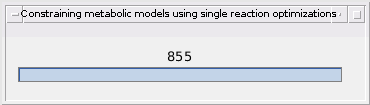

% Compute metabolic models
%wtbr = waitbar(0, '0', 'Name', 'Constraining metabolic models using single reaction optimizations');
reactions_to_optimize = [3753, 3760, 3761, 3762];

for i = 1:length(ia)
    constrainedModel = model;
    for j = 1:length(reactions_to_optimize)
        histoneRxnPos = reactions_to_optimize(j);
        try 
            activity_coef                = table2array(zeta(string(gcp_medium(i)), j));
            if isnan(activity_coef)
                activity_coef = 1E-3;
            end
            mediumModel                  = addMediumConstraints(constrainedModel, string(gcp_medium(i)));    % 1. Add on medium constraints
            mediumModel.c(histoneRxnPos) = activity_coef;
            diffExpGenes                 = findDiffExpGenes(mediumModel, string(gcp_cellnames(i)));          % 3. Find differentially expressed genes for this cancer cell line
            ON_fieldname                 = string(strcat('ON_', string(gcp_cellnames(i))));                  % 4. Make fieldnames for structure
            OFF_fieldname                = string(strcat('OFF_', string(gcp_cellnames(i))));
            [~, soln]                    = CFR(mediumModel, hyperparams, ...
                                               diffExpGenes.(ON_fieldname), ...
                                               diffExpGenes.(OFF_fieldname));
            hist_flux(i, j)              = soln.x(histoneRxnPos);
            hist_grate(i, j)             = soln.x(OBJ);
        catch ME
            warning(strcat('Medium not found for ', string(gcp_cellnames(i)), ...
                           '. Setting to RPMI-1640 as medium.'))
            activity_coef                = table2array(zeta('RPMI', j));
            if isnan(activity_coef)
                activity_coef = 1E-3;
            end
            mediumModel                  = addMediumConstraints(constrainedModel, 'RPMI');                    % 1. Add on medium constraints
            mediumModel.c(histoneRxnPos) = activity_coef;                                                     % 2. Add on histone marker coefficients
            diffExpGenes                 = findDiffExpGenes(mediumModel, string(gcp_cellnames(i)));           % 3. Find differentially expressed genes for this cancer cell line
            ON_fieldname                 = string(strcat('ON_', string(gcp_cellnames(i))));                   % 4. Make fieldnames for structure
            OFF_fieldname                = string(strcat('OFF_', string(gcp_cellnames(i))));
            [~, soln]                    = CFR(mediumModel, hyperparams, ...
                                               diffExpGenes.(ON_fieldname), ...                               % 5. Construct metabolic model
                                               diffExpGenes.(OFF_fieldname));
            hist_flux(i, j)              = soln.x(histoneRxnPos);
            hist_grate(i, j)             = soln.x(OBJ);
            error(i)                     = gcp_cellnames(i);
        end
    %waitbar(i/length(ia), wtbr, sprintf('%d', i))
    end     
end

Save it all

% Save everything
save('~/Data/CBM/eGEM/flux/04292020_SRA_FBA_WT.mat', 'hist_flux');
save('~/Data/CBM/eGEM/flux/04292020_SRA_FBA_WT.mat', '-append', 'hist_grate');
save('~/Data/CBM/eGEM/flux/04292020_SRA_FBA_WT.mat', '-append', 'zeta');

#### Compute medium perturbation fluxes

The `perturbMedium.mlx` function performs medium perturbation experiments by modifying the substrate uptake rate using a predefined factor (10 for increased nutrient uptake, 1E-6 for nutrient restriction). The code is shown below.

% Compute metabolic models
%wtbr = waitbar(0, '0', 'Name', 'Medium perturbation experiments for single reaction optimizations');
reactions_to_optimize = [3753, 3760, 3761, 3762];
load mediumPerturbation.mat mediumPerturbationIDs

hyperparams.eps  = [];
hyperparams.kap  = [];
hyperparams.rho  = [];
hyperparams.mode = true;
hyperparams.eps2 = [];
hyperparams.pfba = true;

for i = 1:length(ia)
    constrainedModel = model;
    for j = 1:length(reactions_to_optimize)
        histoneRxnPos = reactions_to_optimize(j);
        try 
            activity_coef                = table2array(zeta(string(gcp_medium(i)), j));
            if isnan(activity_coef)
                activity_coef = 1E-6;
            end
            mediumModel                  = addMediumConstraints(constrainedModel, string(gcp_medium(i)));    % 1. Add on medium constraints
            mediumModel.c(histoneRxnPos) = activity_coef;
            diffExpGenes                 = findDiffExpGenes(mediumModel, string(gcp_cellnames(i)));          % 3. Find differentially expressed genes for this cancer cell line
            ON_fieldname                 = string(strcat('ON_', string(gcp_cellnames(i))));                  % 4. Make fieldnames for structure
            OFF_fieldname                = string(strcat('OFF_', string(gcp_cellnames(i))));
            %[~, maxFlux]                 = fluxVariability(mediumModel, 99, 'max', ...
            %                                               convertStringsToChars(["biomass_objective";...
            %                                                                      mediumModel.rxns(reactions_to_optimize(j))]), ...
            %                                                                      0, false);
            %mediumModel.ub([OBJ, reactions_to_optimize(j)]) = maxFlux;
            [ON_solution, OFF_solution]  = perturbMedium(mediumModel, OBJ, hyperparams, ...
                                                        mediumPerturbationIDs, ...
                                                        diffExpGenes.(ON_fieldname), ...
                                                        diffExpGenes.(OFF_fieldname));
        catch ME
            warning(strcat(gcp_medium(i), 'Medium not found for ', string(gcp_cellnames(i)), ...
                           '. Setting to RPMI-1640 as medium.'))
            activity_coef                = table2array(zeta('RPMI', j));
            if isnan(activity_coef)
                activity_coef = 1E-6;
            end
            mediumModel                  = addMediumConstraints(constrainedModel, 'RPMI');                    % 1. Add on medium constraints
            mediumModel.c(histoneRxnPos) = activity_coef;                                                     % 2. Add on histone marker coefficients
            diffExpGenes                 = findDiffExpGenes(mediumModel, string(gcp_cellnames(i)));           % 3. Find differentially expressed genes for this cancer cell line
            ON_fieldname                 = string(strcat('ON_', string(gcp_cellnames(i))));                   % 4. Make fieldnames for structure
            OFF_fieldname                = string(strcat('OFF_', string(gcp_cellnames(i))));
            %[~, maxFlux]                 = fluxVariability(mediumModel, 99, 'max', ...
            %                                               convertStringsToChars(["biomass_objective";...
            %                                                                      mediumModel.rxns(reactions_to_optimize(j))]), ...
            %                                                                      0, false);
            %mediumModel.ub(OBJ) = maxFlux;
            
            [ON_solution, OFF_solution]  = perturbMedium(mediumModel, OBJ, hyperparams, ...
                                                         mediumPerturbationIDs, ...
                                                         diffExpGenes.(ON_fieldname), ...
                                                         diffExpGenes.(OFF_fieldname));
            error(i)                     = gcp_cellnames(i);
        end
    end
    supplement_all_flux{i, j}     = ON_solution.ONFluxes;
    supplement_hist_flux{i, j}    = ON_solution.ONFluxes(:, histoneRxnPos);
    supplement_grate{i, j}        = ON_solution.ONGrate;
    deprivation_all_flux{i, j}    = OFF_solution.OFFluxes;
    deprivation_hist_flux{i, j}   = OFF_solution.OFFluxes(:, histoneRxnPos);
    deprivation_grate{i, j}       = OFF_solution.OFFGrate;
    %waitbar(i/length(ia), wtbr, sprintf('%d', i))
end

Save everything

save('~/Data/CBM/eGEM/flux/04292020_SRA_FBA_MP.mat', 'supplement_all_flux');
save('~/Data/CBM/eGEM/flux/04292020_SRA_FBA_MP.mat', '-append', 'supplement_hist_flux');
save('~/Data/CBM/eGEM/flux/04292020_SRA_FBA_MP.mat', '-append', 'supplement_grate');
save('~/Data/CBM/eGEM/flux/04292020_SRA_FBA_MP.mat', '-append', 'deprivation_all_flux');
save('~/Data/CBM/eGEM/flux/04292020_SRA_FBA_MP.mat', '-append', 'deprivation_hist_flux');
save('~/Data/CBM/eGEM/flux/04292020_SRA_FBA_MP.mat', '-append', 'deprivation_grate');

#### Competition reaction optimization (`zeta` from FBA)

load zeta_cra.mat;
zeta

zeta = 41×4 table
                               DM_KAC       DM_KMe1      DM_KMe2       DM_KMe3  
                             __________    _________    __________    __________

    ACL4                      0.0001049    0.0062036       0.48392      0.012642
    AlphaMEM                 8.6168e-09     0.001057    0.00053706    5.5562e-05
    DMEM                        0.01181     0.081436     0.0025566       0.02065
    DMEMwGlc                   0.011073      0.18484     0.0011907       0.74878
    DMEMwGln                    0.01053      0.35467     0.0054815        0.4342
    DMEMwPyr                  0.0083299      0.01306     0.0021528        0.2211
    DMEMwGlnwPyr               0.011725      0.12602    7.8081e-06       0.155

#### Compute wild type fluxes

This module computes the wild type fluxes using the new zeta values.

% Compute metabolic models
%wtbr = waitbar(0, '0', 'Name', 'Constraining metabolic models using single reaction optimizations');
reactions_to_optimize = [3753, 3760, 3761, 3762];

for i = 1:length(ia)
    constrainedModel = model;
    for j = 1:length(reactions_to_optimize)
        histoneRxnPos = reactions_to_optimize(j);
        try 
            activity_coef                = table2array(zeta(string(gcp_medium(i)), j));
            if isnan(activity_coef)
                activity_coef = 1E-3;
            end
            mediumModel                  = addMediumConstraints(constrainedModel, string(gcp_medium(i)));    % 1. Add on medium constraints
            mediumModel.c(histoneRxnPos) = activity_coef;
            diffExpGenes                 = findDiffExpGenes(mediumModel, string(gcp_cellnames(i)));          % 3. Find differentially expressed genes for this cancer cell line
            ON_fieldname                 = string(strcat('ON_', string(gcp_cellnames(i))));                  % 4. Make fieldnames for structure
            OFF_fieldname                = string(strcat('OFF_', string(gcp_cellnames(i))));
            [~, soln]                    = CFR(mediumModel, hyperparams, ...
                                               diffExpGenes.(ON_fieldname), ...
                                               diffExpGenes.(OFF_fieldname));
            hist_flux(i, j)              = soln.x(histoneRxnPos);
            hist_grate(i, j)             = soln.x(OBJ);
        catch ME
            warning(strcat('Medium not found for ', string(gcp_cellnames(i)), ...
                           '. Setting to RPMI-1640 as medium.'))
            activity_coef                = table2array(zeta('RPMI', j));
            if isnan(activity_coef)
                activity_coef = 1E-3;
            end
            mediumModel                  = addMediumConstraints(constrainedModel, 'RPMI');                    % 1. Add on medium constraints
            mediumModel.c(histoneRxnPos) = activity_coef;                                                     % 2. Add on histone marker coefficients
            diffExpGenes                 = findDiffExpGenes(mediumModel, string(gcp_cellnames(i)));           % 3. Find differentially expressed genes for this cancer cell line
            ON_fieldname                 = string(strcat('ON_', string(gcp_cellnames(i))));                   % 4. Make fieldnames for structure
            OFF_fieldname                = string(strcat('OFF_', string(gcp_cellnames(i))));
            [~, soln]                    = CFR(mediumModel, hyperparams, ...
                                               diffExpGenes.(ON_fieldname), ...                               % 5. Construct metabolic model
                                               diffExpGenes.(OFF_fieldname));
            hist_flux(i, j)              = soln.x(histoneRxnPos);
            hist_grate(i, j)             = soln.x(OBJ);
            error(i)                     = gcp_cellnames(i);
        end
    %waitbar(i/length(ia), wtbr, sprintf('%d', i))
    end     
end

Save it all

% Save everything
save('~/Data/CBM/eGEM/flux/04292020_CRA_FBA_WT.mat', 'hist_flux');
save('~/Data/CBM/eGEM/flux/04292020_CRA_FBA_WT.mat', '-append', 'hist_grate');
save('~/Data/CBM/eGEM/flux/04292020_CRA_FBA_WT.mat', '-append', 'zeta');

#### Compute medium perturbation fluxes

All histone reactions was computed with the objective function 100 times. The final `zeta` value that was selected had the maximum variance across all histone reactions and that had high growth.

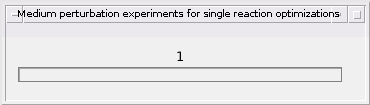


Interrupt request received


%wtbr = waitbar(0, '0', 'Name', 'Medium perturbation experiments for single reaction optimizations');
reactions_to_optimize = [3753, 3760, 3761, 3762];
load mediumPerturbation.mat mediumPerturbationIDs

hyperparams.eps  = [];
hyperparams.kap  = [];
hyperparams.rho  = [];
hyperparams.mode = true;
hyperparams.eps2 = [];
hyperparams.pfba = true;

for i = 1:length(ia)
    constrainedModel = model;
    histoneRxnPos = reactions_to_optimize;
    try 
        activity_coef                = table2array(zeta(string(gcp_medium(i)), :));
        %activity_coef(isnan(activity)) = 1E-3;
        
        mediumModel                  = addMediumConstraints(constrainedModel, string(gcp_medium(i)));    % 1. Add on medium constraints
        mediumModel.c(histoneRxnPos) = activity_coef;
        diffExpGenes                 = findDiffExpGenes(mediumModel, string(gcp_cellnames(i)));          % 3. Find differentially expressed genes for this cancer cell line
        ON_fieldname                 = string(strcat('ON_', string(gcp_cellnames(i))));                  % 4. Make fieldnames for structure
        OFF_fieldname                = string(strcat('OFF_', string(gcp_cellnames(i))));
                    
        [ON_solution, OFF_solution]  = perturbMedium(model, OBJ, hyperparams, ...
                                                    mediumPerturbationIDs, ...
                                                    diffExpGenes.(ON_fieldname), ...
                                                    diffExpGenes.(OFF_fieldname));
    catch ME
        warning(strcat(gcp_medium(i), 'Medium not found for ', string(gcp_cellnames(i)), ...
                                      '. Setting to RPMI-1640 as medium.'))
        activity_coef                = table2array(zeta('RPMI', :));
        %activity_coef(isnan(activity)) = 1E-3;

        mediumModel                  = addMediumConstraints(constrainedModel, 'RPMI');                    % 1. Add on medium constraints
        mediumModel.c(histoneRxnPos) = activity_coef;                                                     % 2. Add on histone marker coefficients
        diffExpGenes                 = findDiffExpGenes(mediumModel, string(gcp_cellnames(i)));           % 3. Find differentially expressed genes for this cancer cell line
        ON_fieldname                 = string(strcat('ON_', string(gcp_cellnames(i))));                   % 4. Make fieldnames for structure
        OFF_fieldname                = string(strcat('OFF_', string(gcp_cellnames(i))));
        
        [ON_solution, OFF_solution]  = perturbMedium(model, OBJ, hyperparams, ...
                                                     mediumPerturbationIDs, ...
                                                     diffExpGenes.(ON_fieldname), ...
                                                     diffExpGenes.(OFF_fieldname));
        error(i)                     = gcp_cellnames(i);
    end
    supplement_all_flux{i, 1}     = ON_solution.ONFluxes;
    supplement_hist_flux{i, 1}    = ON_solution.ONFluxes(:, histoneRxnPos);
    supplement_grate{i, 1}        = ON_solution.ONGrate;
    deprivation_all_flux{i, 1}    = OFF_solution.OFFluxes;
    deprivation_hist_flux{i, 1}   = OFF_solution.OFFluxes(:, histoneRxnPos);
    deprivation_grate{i, 1}       = OFF_solution.OFFGrate;
    %waitbar(i/length(ia), wtbr, sprintf('%d', i))
end

Save everything

save('~/Data/CBM/eGEM/flux/04292020_CRA_FBA_MP.mat', 'supplement_all_flux');
save('~/Data/CBM/eGEM/flux/04292020_CRA_FBA_MP.mat', '-append', 'supplement_hist_flux');
save('~/Data/CBM/eGEM/flux/04292020_CRA_FBA_MP.mat', '-append', 'supplement_grate');
save('~/Data/CBM/eGEM/flux/04292020_CRA_FBA_MP.mat', '-append', 'deprivation_all_flux');
save('~/Data/CBM/eGEM/flux/04292020_CRA_FBA_MP.mat', '-append', 'deprivation_hist_flux');
save('~/Data/CBM/eGEM/flux/04292020_CRA_FBA_MP.mat', '-append', 'deprivation_grate');

#### Single histone reaction optimization (`zeta` from FVA)

Each individual histone reaction was maximized with the objective function 100 times. The final `zeta` value that was selected had the maximum variance across all histone reactions and that had high growth.

#### Competition reaction optimization (`zeta` from FVA)

Each individual histone reaction was maximized with the objective function 100 times. The final `zeta` value that was selected had the maximum variance across all histone reactions and that had high growth.

### Cell line specific experiments

These experiments computed `zeta` values that were specific to individual cancer cell lines in the CCLE data repository. In total, there are 865 sets of zeta values for 4 different histone reactions.

#### Single histone reaction optimization (`zeta` from FBA)

Each individual histone reaction flux was computed with the objective function 100 times. The final `zeta` value that was selected had the maximum variance across all histone reactions and that had high growth.

#### Competition reaction optimization (`zeta` from FBA)

All histone reactions was computed with the objective function 100 times. The final `zeta` value that was selected had the maximum variance across all histone reactions and that had high growth.

#### Single histone reaction optimization (`zeta` from FVA)

Each individual histone reaction was maximized with the objective function 100 times. The final `zeta` value that was selected had the maximum variance across all histone reactions and that had high growth.

#### Competition reaction optimization (`zeta` from FVA)

Each individual histone reaction was maximized with the objective function 100 times. The final `zeta` value that was selected had the maximum variance across all histone reactions and that had high growth.